READ ME

-This is a code to find the displacement field of a beam using the method of FEM.

-Boundary condition 2 for both ends.

-k can be 0 or any other number.

-axial force distribution can be a number or a function of x.

-polynomial basis function of the type: 1 + x + x^2 + x^3 + ..... + x^N is used.

Clear all stored variables and commands

clear all
clc

Define basic settings

format long % for bettter accuracy
syms x % symbolic toolbox for handling polynomials

Getting the basic inputs

EA = input('EA = ')

EA =      1


k = input('spring constant assosciated with the member, k = ')

k =     10


L = input('Length of Beam = ')

L =      1


N = input('Order of polynomial = ')+1

N =      2


while true
    f = input('Distribution (use small letter "x" if it is a variable) of axial force = ')

f =     10


Boundary condition at x = 0

    while true
        type_0 = input('Enter the type of boundary condition(1,2,or3) at x = 0:   ')

        if type_0 == 1
            U_0 = input('Give the displacement at the end x = 0 :  ')
            break
        elseif type_0 == 2
            P_0 = input('Give the force at the end x = 0 :  ')
            break
        elseif type_0 == 3
            k_spring = input('Give the value of connected spring constant :  ') % Please understand the difference between K , k , k_spring
            delta_0 = input('Give the extension of the connected spring at the end x = 0 :  ')
            break
        else
            fprintf('Error, Boundary condition must be any of of type 1 / type 2 or type 3 ')
            continue
        end
    end

type_0 =      2


P_0 =      5


Boundary condition at x = L

    while true
        type_L = input('Enter the type of boundary condition(1,2,or3) at x = L:   ')

        if type_L == 1
            U_L = input('Give the displacement at the end x = L :  ')
            break
        elseif type_L == 2
            P_L = input('Give the force at the end x = L :  ')
            break
        elseif type_L == 3
            k_spring = input('Give the value of connected spring constant :  ') % Please understand the difference between K , k , k_spring
            delta_L = input('Give the extension of the connected spring at the end x = L :  ')
            break
        else
            fprintf('Error, Boundary condition must be any of of type 1 / type 2 or type 3 ')
            continue
        end
    end

type_L =      2


P_L =     10


Initializing

Phi = sym(zeros(N,1));
K = zeros(N); % Please understand the difference between K , k , k_spring: This K is the stiffness matrix
F = zeros(N,1);

Establishing the Basis functions

for i = 1:N
    Phi(i) = x^(i-1);
end
dPhi = diff(Phi);
Phi

$$Phi = \left(\begin{array}{c} 1\\ x \end{array}\right)$$

dPhi

$$dPhi = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

Verifying the Force Equilibrium

    if k == 0
        if int(f*Phi(1),0,L) + P_L - P_0 == 0
            break
        else
            fprintf('If spring constant assosciated with the member, k = 0, then,\n there must be a force equilibrium balance to have a solution.\n Kindly update the values of forces at both ends and the axial\n distribution of forces accordingly.')
            continue
        end
    else
        break
    end
end


Calculating the Stiffness Matrix  and the Force vector

if type_0 && type_L == 2
    for i = 1:N
        for j = 1:N
            K(i,j) = int(EA*dPhi(i)*dPhi(j)+k*Phi(i)*Phi(j),x,0,L);
        end
        F(i,1) = int(f*Phi(i),x,0,L) + subs(P_L*Phi(i),x,L) - subs(P_0*Phi(i),x,0);
    end
end
K

K =   10.000000000000000   5.000000000000000
   5.000000000000000   4.333333333333333


F

F =     15
    15


Computing the Solution

if type_0 && type_L == 2
    if k == 0
        K(1,:) = 0;
        K(:,1) = 0;
        K(1,1) = 1;
        fprintf('Since k = 0, with boundary condition type-2 at both ends\n there are infinite possible solutions. Out of the infinite solutions possible, \n one solution where the displacement at x = 0 is displayed!')
    end
end

Alpha = K\F;
U = vpa(Alpha'*Phi)

$$U = 4.0909090909090909090909090909091\,x-0.54545454545454545454545454545455$$

`Plotting 

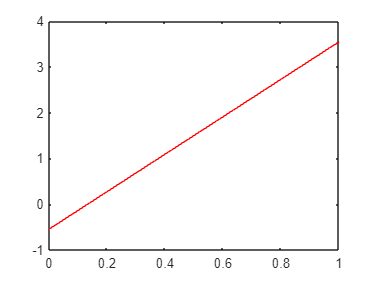

t = linspace(0,L,100);
u = subs(U,x,t);
figure()
plot(t,u,'r','Linewidth',0.2)